初版：2021年11月27日

# シミュレーション　講義ノート No.1

#### 藤原　哉

#### 農林中央金庫

### 1. はじめに

本講義ではシミュレーションの中でもモンテカルロ・シミュレーションについて解説・実習を行う。

モンテカルロ・シミュレーションとは乱数を用いるシミュレーションの総称である。乱数を用いることから不確実性を含むものを対象にすることが基本である。ただし、確定的な問題を確率的な問題として表現することによりモンテカルロ・シミュレーションで解くこともできる。

ファイナンスでは将来の不確実性を扱うことが多いためモンテカルロ・シミュレーションは実務・研究の両方において有用なツールである。モンテカルロ・シミュレーションは多次元の問題を容易に評価することができ、プログラム実装もあまり難しくない。しかし、決して万能ツールではなく、弱点や適用が困難な問題など限界もある。

本講義は、モンテカルロ・シミュレーションの基本的な方法だけでなく、弱点・適用範囲などの限界を理解し、その限界を乗り越えようとする様々な手法を座学とプログラミング実習を通じて習得することを目的としている。

### 2. 乱数について

　モンテカルロ・シミュレーションでは乱数は基本要素であるが、乱数の定義は意外と難しい。杉田(2014)によると、乱数の定義は、計算可能理論に基づいてKolmogorov-Chaitinが複雑性の概念を導入して行っている。Kolmogorov-Chaitinの定義からは、コンピュータで乱数を生成することが不可能であることが示されている。

　乱数は生成できないが、「乱数らしきもの」をコンピュータで生成することはできる。これを擬似乱数という。乱数の確率論的な性質はわかっているので、擬似乱数が乱数に近いかは統計的な検定で調べることが可能である。多くの文献では誤解の生じない範囲で擬似乱数を乱数と表記している。本講義でも以降は擬似乱数のことも乱数と表記する。

　モンテカルロ・シミュレーションの教科書では、一様乱数の生成方法を示し、一様乱数から確率分布に従う乱数を生成する方法を解説するパターンが多い。ただし、現状では多様な確率分布に従う乱数を生成する関数(ライブラリー)が利用可能である(MATLABにも高機能な乱数生成関数がある)。よって、応用を重視する場合には生成方法の詳細について学習する意義は薄れているため、本講義では生成方法の解説はしない。

一様乱数の生成方法や検定について興味のある人は伏見(1989)を参照のこと。

#### Matlabでの擬似乱数生成

　Matlabには一様乱数生成用関数 rand 、正規乱数生成用関数 randn、が標準の組込み関数として用意されている。

clear; 

v = rand(10,2); % [0,1]の一様乱数を10行2列生成する。
disp(v);

    0.1575    0.0477
    0.1446    0.7153
    0.6588    0.7391
    0.9820    0.9398
    0.5053    0.0638
    0.3224    0.2245
    0.5962    0.3211
    0.2186    0.3971
    0.8130    0.9477
    0.3649    0.1002



v = randn(10,2); % 平均0, 分散1の標準正規乱数を10行2列生成する。
disp(v);

    1.5654   -1.1073
    1.7969   -0.0507
   -0.4129   -1.4132
   -0.7556   -0.3643
    1.6294   -0.8743
    0.9018   -0.3000
   -0.4978    0.7959
   -0.2768    0.1069
    0.1940    1.8086
   -2.2923    0.5351



MatlabのアドンであるStatistics and Machine Learning Toolboxがあれば主要な分布に従う乱数を簡単に発生させることができる（都立大の環境ではインストールされているはず）。

まず makedist関数を用いて分布情報保持のための構造体を生成し、分布固有のパラメータを設定する。次に、分布情報の構造体を用いてrandom関数により乱数を生成する。

例として、強度が0.1（平均が10)の指数分布に従う乱数の生成方法を示す。

pd = makedist('Exponential'); % 指数分布の情報を持つ構造体を生成
pd.mu = 10; %平均（強度の逆数）を10と指定
v = random(pd,10,2); % pdの情報（ここでは指数分布）に従う乱数を10行2列で生成する。
disp(v);

   11.5953   10.5049
    0.5030    0.0658
    3.0660    8.5828
   41.5387   13.2751
    4.6246    1.9993
   39.1522   21.6084
    6.6287   12.0276
   16.0213    5.1647
   16.3919   20.2487
    9.1341   15.3705



makedist関数、random関数の詳細についてはdoc makedist、doc random としてオンラインドキュメントで確認できる。

#### シミュレーション結果の確認

シミュレーションの結果を視覚的に確認したいときにはヒストグラムを作成する。Matlabでは関数 histogramを使うことでヒストグラムを簡単に作ることが出来る。

histogram関数の戻値の変数（クラスオブジェクト）を変更することで表示を調整することができる。

例：一様分布乱数列の経験分布関数の表示

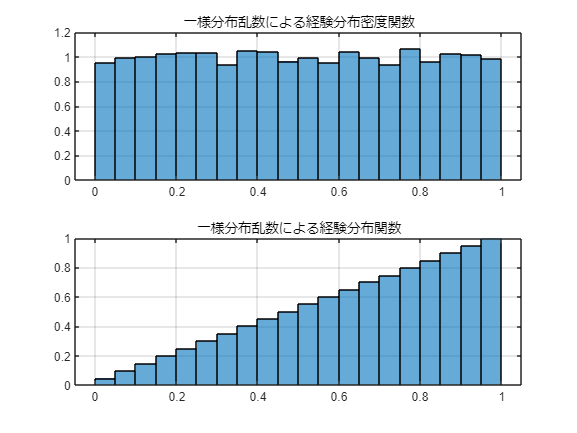

v = rand(10000,1); %[0,1]の一様分布乱数を１万個生成する。

% 密度関数の表示
nfig = 1; 
figure(nfig); subplot(211); hhdl1 = histogram(v); grid; title('一様分布乱数による経験分布密度関数');
hhdl1.NumBins = 20; % binの数(分割数） 
hhdl1.Normalization = "pdf"; %密度関数として表示
%% 分布関数の表示
figure(nfig); subplot(212); hhdl2 = histogram(v); grid; title('一様分布乱数による経験分布関数');
hhdl2.NumBins = 20; % binの数(分割数） 
hhdl2.Normalization = "cdf"; %分布関数として表示

histogram関数の戻値の中身

disp(hhdl1);

  Histogram のプロパティ:

             Data: [10000×1 double]
           Values: [0.9520 0.9940 1.0020 1.0240 1.0340 1.0360 0.9380 1.0480 1.0420 0.9640 0.9960 0.9500 1.0420 0.9920 … ]
          NumBins: 20
         BinEdges: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 … ]
         BinWidth: 0.0500
        BinLimits: [0 1]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を表示



例：標準正規分布乱数列の経験分布関数の表示

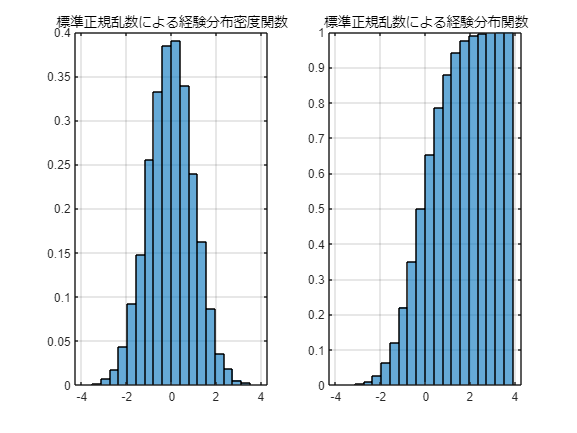

v = randn(10000,1); % 平均0,分散1の標準正規乱数を１万個生成する。
%% 密度関数の表示
nfig = 2; 
figure(nfig); subplot(121);hhdl3 = histogram(v); grid; title('標準正規乱数による経験分布密度関数');
hhdl3.NumBins = 20; 
hhdl3.Normalization = 'pdf';

%% 分布関数の表示
figure(nfig); subplot(122);hhdl4 = histogram(v); grid; title('標準正規乱数による経験分布関数');
hhdl4.NumBins = 20; 
hhdl4.Normalization = 'cdf'; 

例：指数分布乱数列の経験分布関数の表示

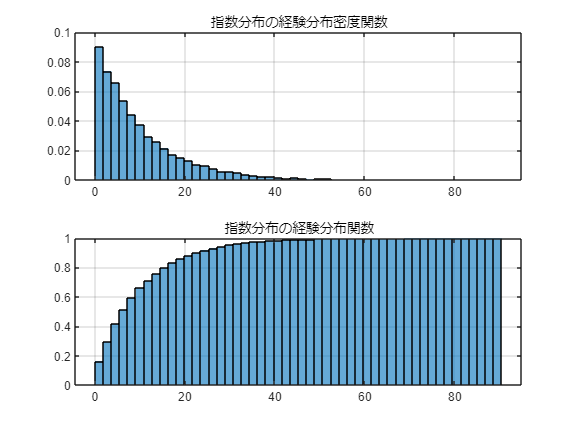

pd = makedist('Exponential'); % 指数分布の情報を持つ構造体を生成
pd.mu = 10; %平均（強度の逆数）を10と指定
v = random(pd,10000,1); % pdの情報（ここでは指数分布）に従う乱数を10000行１列で生成する。
%% 密度関数の表示
nfig = 3;
figure(nfig);subplot(211); hhdl5 = histogram(v); grid; title('指数分布の経験分布密度関数');
hhdl5.NumBins = 50; hhdl5.Normalization = 'pdf';
%% 分布関数の表示
figure(nfig);subplot(212); hhdl6 = histogram(v); grid; title('指数分布の経験分布関数');
hhdl6.NumBins = 50; hhdl6.Normalization = 'cdf';

### 3. 数学的な裏付け

　モンテカルロ・シミュレーションは、確率変数の分布に従ってサンプリングを行い期待値の近似的な値を得る方法である。サンプリングによる計算で「真の値」に収束することを保証しているのが大数の法則である。近似誤差を評価する方法は中心極限定理から導かれる。大数の法則と中心極限定理の証明に興味のある人は確率論の教科書(船木(2004)など）を参照のこと。

#### 大数の法則

大数の法則には弱法則（確率収束）と強法則(概収束）がある。弱法則と強法則での仮定の違いは実務的にはあまり影響せず、両者の違いを意識することはほとんどない。

**大数の弱法則**

確率変数 $X_1,X_2,\cdots X_N$が独立で同分布(IID)とする。平均$\mu = \mathbb{E}\left[ X_1 \right]$と分散 $\sigma^2 = {\rm Var} \left[X_1\right]$が存在するとする。このとき、

 
$$\frac{1}{N} \sum_{i=1}^{N} X_i \longrightarrow \mu = \mathbb{E}\left[X_1\right],  \ {\rm as} \ N \longrightarrow \infty$$


となる。ただし、確率収束である。

**大数の強法則**

確率変数 $X_1,X_2,\cdots X_N$が独立で同分布(IID)とする。 $X_1$が可積分 $\mathbb{E} \left [\left\vert X_1 \right\vert \right] \lt \infty$ とする。このとき、

 
$$\frac{1}{N} \sum_{i=1}^{N} X_i \longrightarrow \mu = \mathbb{E}\left[X_1\right],  \ {\rm as} \ N \longrightarrow \infty$$


となる。ただし、概収束である。

大数の法則より、確率変数のサンプリングによる平均値はサンプル数が十分に大きいと真の期待値に収束することがわかる（モンテカルロ・シミュレーションの心の支え）。

**収束の例**

　確率変数$X_1,X_2,\cdots X_N$が独立で標準正規分布に従うとする。 $N$を増やしたとき  $\frac{1}{N} \sum_{i=1}^{N} X_i$の振る舞いを確認する。

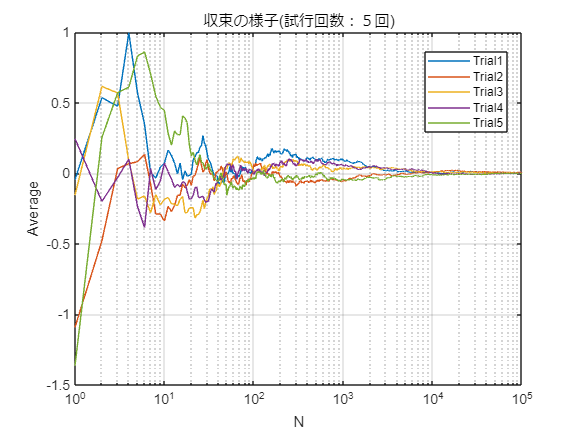

clear;

Nsim = 100000; 
X = randn(5,Nsim); % 標準正規分布に従う乱数生成 5xNmax行列で出力
ave = cumsum(X,2)./(1:Nsim); 
nfig = 4; 
figure(nfig);semilogx(1:Nsim,ave,'-'); grid; legend('Trial1','Trial2','Trial3','Trial4','Trial5',"Location","best");
title('収束の様子(試行回数：５回)');xlabel('N'); ylabel('Average');

実際のシミュレーションでは有限のサンプル数で評価するため誤差が生じる。中心極限定理により誤差の大きさの見積もりが可能となる。

**中心極限定理**

確率変数 $X_1,X_2,\cdots$が独立で同分布(IID)とする。平均$\mu = \mathbb{E}\left[ X_1 \right]$と分散 $\sigma^2 = {\rm Var} \left[X_1\right]$が存在するとする。このとき、


$$\sqrt{N} \left(\frac{1}{N} \sum_{i=1}^{N} X_i - \mu \right) \longrightarrow N \left( 0,\sigma^2 \right), \ {\rm as} \ N \longrightarrow \infty$$


となる。ただし、分布収束である。

中心極限定理より、十分に大きな $N$ では

 
$$\frac{1}{N}\sum_{i=1}^{N} X_i \sim N \left(\mu, \frac{\sigma^2}{N} \right)$$


となり、 $\sigma$が既知であれば 誤差の見積もりが出来ることになる。

**誤差の見積もりの例**

確率変数$X_1,X_2,\cdots$が独立で標準正規分布に従うとする。このとき $N$を増やしたとき  $\frac{1}{N} \sum_{i=1}^{N} X_i$の誤差（両側1%点)とシミュレーションでの値を確認する。

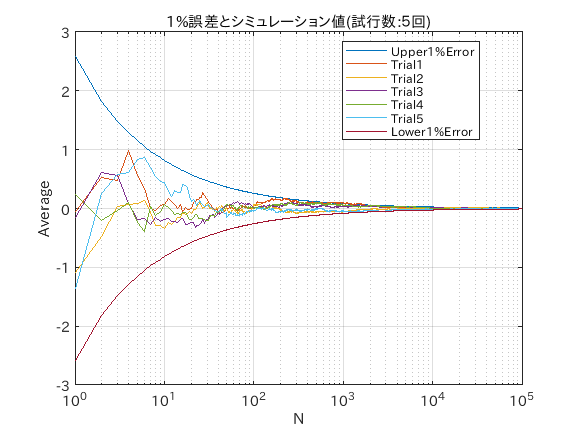

cicoeff = norminv(0.995); 
upper = cicoeff./sqrt(1:Nsim); %両側1%誤差の上方
lower = -cicoeff./sqrt(1:Nsim);%両側1%誤差の下方
nfig = 5; 
figure(nfig);fh2 = semilogx(1:Nsim,[upper;ave;lower],'-'); grid; 
legend('Upper1%Error','Trial1','Trial2','Trial3','Trial4','Trial5','Lower1%Error',"Location","best");
fh2(1).Parent.XLabel.String = "N";
fh2(1).Parent.YLabel.String = "Average";
fh2(1).Parent.Title.String = "1%誤差とシミュレーション値(試行数:５回)";

**実際の誤差見積もり：Sectioning**

 　中心極限定理を利用した誤差の見積もりでは母集団の分散 $\sigma^2$が既知であることが前提となっている。しかし、実際には $\sigma^2$がわかっていることは稀であるため、簡易な誤差評価としては試行を複数回行い推定値の標本分散 $\hat{\sigma^2}$を $\sigma^2$の代替とする方法がある。この方法では標本分散の推定誤差を無視している点に注意が必要がある。

　母集団の分散 $\sigma^2$に依存せずに誤差を推定する方法にSectioningがある。Sectioningでは推定を複数回行い、その標本平均と不偏分散からt分布に従う統計量を算出し、それを用いて信頼区間を求める。推定を繰り返す回数を $M$とし、 $i$回目の推定結果を $A_N^i = \frac{1}{N} \sum_{n=1}^N X_{n,i}$ とする。 $A_N^i$の標本平均を $\bar{A}_N$, 不偏分散を $\bar{V}_N$とする。


$$\bar{A}_N = \frac{1}{M} \sum_{i=1}^{M} A_{N}^{i} \\
\bar{V}_N = \frac{1}{M-1} \sum_{i=1}^{M} \left( A_N^i - \bar{A}_N \right)^2$$


このとき

 
$${\rm err}_N = \sqrt{M}\frac{\bar{A}_N - \mu}{\sqrt{\bar{V}_N}}$$


は $N\rightarrow \infty$において自由度 $M-1$のt分布に従う。よって、 $N$が十分に大きい場合には確率 $1-\alpha$での信頼区間は

 
$$\mu \in \left[\bar{A}_N - t^{-1} \left(1 - \frac{\alpha}{2}, M-1 \right) \sqrt{\frac{\bar{V}_N}{M}},\bar{A}_N + t^{-1} \left(1 - \frac{\alpha}{2}, M-1 \right) \sqrt{\frac{\bar{V}_N}{M}}  \right]$$


となる。ただし、 $t^{-1}(x,n)$は自由度$n$のt分布の逆関数である。本講義では、Sectioningで結果を評価することを基本とする。

例として標準正規乱数の平均を1000個の乱数で求める。真の平均値である０が信頼区間に含まれるか確かめてみる。

推定の繰返し100回として有意水準を1%のときの信頼区間を計算する。

clear;

Nsim = 1000; 
alp = 0.01; % 有意水準
nTrial = 100;
vs = zeros(nTrial,1); 
for iloop = 1:nTrial
    v = randn(Nsim,1); 
    vs(iloop,1) = mean(v);
end
rst = estConfidenceInterval(vs,alp);% 信頼区間の計算用の関数（演習で作成する）
disp(rst);

     CILower       CIUpper     Ntrial    alpha
    __________    _________    ______    _____

    -0.0077172    0.0089253     100      0.01 



100回の推定値の分布（ヒストグラム）を示す。

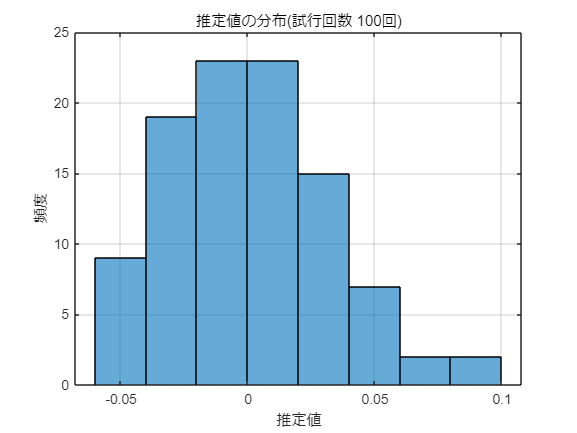

nfig = 6;
figure(nfig); histogram(vs); grid; title('推定値の分布(試行回数 100回)'); xlabel('推定値'); ylabel('頻度');

#### 推定値の信頼区間算出のための関数

　Sectioningでは複数回行った推定結果から有意水準に基づいて信頼区間を求める。この操作を実行する関数を生成する。

この関数の名前を estConfidenceIntervalとする。estConfidenceIntervalの入力は複数の推定結果を含む実数値ベクトルと有意水準であり、出力は信頼区間の下限と上限である。

**ミニ課題**

estConfidenceInterval関数をestConfidenceInterval.mとして保存しよう。estConfidenceInterval.mは今後の授業で利用する。

指数分布(平均 10)に従う乱数を1000個発生させて平均値を求める場合の信頼区間を推定するスクリプトを作成せよ。

ただし、推定の繰り返し回数を100、有意水準を1%としてestConfidenceIntervalを用いよ。また、100回繰返した推定値のヒストグラムを表示せよ。

clear;

pd = makedist('Exponential'); % 指数分布の情報を持つ構造体を生成
pd.mu = 10; %平均（強度の逆数）を10と指定
Nsim = 1000; 
nTrial = 100; 
vs = zeros(nTrial,1); 
rng('default');
for iloop = 1:nTrial
    vs(iloop,1) = mean(random(pd,Nsim,1)); % 1000回の平均 
end
alpha = 0.01; %有意水準
rst = estConfidenceInterval(vs,alpha);
disp(rst);

    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    9.9114     10.086      100      0.01 



#### 練習課題：イカサマサイコロを作る

普通のサイコロは1から6まで均等の確率$\frac{1}{6}$で出現する。これは組込関数randiで簡単に実現できる。

サイコロを10000回試行したときの出現確率をヒストグラムで表示すると、多少の誤差はあるがほぼ均等であることがわかる。

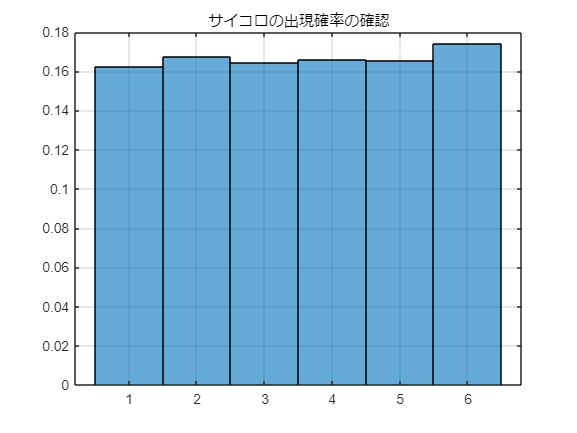

v = randi(6,10000,1); % 1,2,3,4,5,6が均等に発生する乱数を10000個生成する。
nfig = 7; 
figure(nfig); hhdl7 = histogram(v);grid; title('サイコロの出現確率の確認');
hhdl7.Normalization = 'probability'; 

課題１：偶数の出現確率が奇数の出現確率の２倍となるイカサマサイコロ関数を作成する。

　　　　関数の引数は生成したい乱数の数とし、戻り値は乱数値のベクトルとする。関数名をmyDiceとすると

　　　　100回の試行は次のように計算することになる。

              作成した関数でシミュレーションを行い、サイコロの出目の分布密度関数のヒストグラムを作成し偶数の出現確率が奇数の２倍となっていることを確認せよ

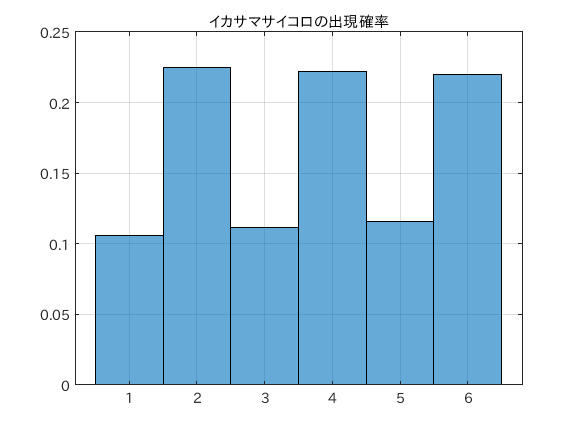

% 課題１の確認
v = myDice(10000);
nfig = 8; 
figure(nfig);hhdl8 = histogram(v);grid; title('イカサマサイコロの出現確率');
hhdl8.Normalization = 'probability';

課題２：サイコロの出る値の偶数・奇数を予想し予想が当たるとポイントが２倍、外れるとポイントを失うゲームを考える。

　　　　毎回100ポイントを賭ける。このとき、１回あたりの損益は予想が当たると+100,外れると-100とする。

　　　　毎回偶数が出ると予想すると仮定する。この場合にはサイコロの出目が偶数であれば＋100, 奇数であれば-100の損益となる。

　　　　10回ゲームを行ったときの損益をシミュレーションで求める関数を作成せよ。また、10回ゲームでの損益計算を100回繰り返して10回ゲーム損益のヒストグラムを作成し、

　　　　有意水準1%での信頼区間を推定せよ。

　　　　なお、サイコロには課題１で作成したイカサマサイコロを用いる。

課題２’：イカサマサイコロではなく普通のサイコロを使うとどうなるか確認せよ。

課題２’’：１回のあたりの損益がサイコロの出目が3以下であれば+100、4以上であれば-100とする。

                常に３以下になると予想する。この場合にはサイコロの出目が３以下であれば＋100,奇数であれば-100の損益となる。

　　　　 課題２と同じ条件で損益シミュレーションを行い、ヒストグラムの作成・1%信頼区間の推定を実行せよ。

計算例

%課題２の確認
nGame = 10; 
nTrial = 100;
pls = zeros(nTrial,1);
for iloop = 1:nTrial
    pls(iloop,1) = myGame(nGame);
end
alpha = 0.01; 
rst = estConfidenceInterval(pls,alpha);
disp(rst); 

    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    -196.49    -11.506     100      0.01 



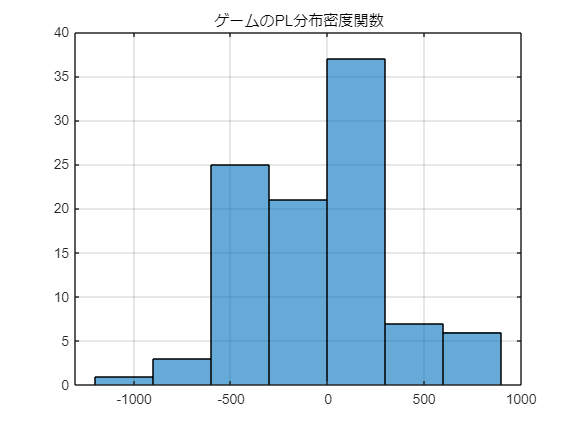

nfig = 9;
figure(7);hhdl9 = histogram(pls);grid;title('ゲームのPL分布密度関数');
hhdl9.Normalization = 'count';

### ローカル関数

function v = myDice(nSim)
    %% イカサマ・サイコロ
    % 偶数の出現確率が奇数の出現確率の２倍
    arguments
        nSim (1,1) {mustBeInteger,mustBePositive} % 試行回数
    end
    % イカサマサイコロ（偶数の出る確率が奇数の出る確率の２倍）
    v = randi(9,nSim,1);
    v(eq(v,7)) = 2; % 出目が7の場合は2とみなす 
    v(eq(v,8)) = 4; % 出目が8の場合は4とみなす
    v(eq(v,9)) = 6; % 出目が9の場合は6とみなす。
end

function pl = myGame(nGame)
    %% 課題２のゲームでの損益計算
    arguments
        nGame (1,1) {mustBeInteger,mustBePositive} %ゲームの回数
    end
    v = myDice(nGame);
%    v = randi(6,nGame,1);
    vv = zeros(size(v));

%     vv(eq(mod(v,2),0)) = 100; % 出目が偶数：勝ちなので100ポイント益
%     vv(eq(mod(v,2),1)) = -100; % 出目が奇数：負けなので100ポイント損
    
    vv(le(v,3)) = 100; % 出目が３以下だと勝ちなのでポイント100益
    vv(ge(v,4)) = -100; % 出目が４以上だと負けなのでポイント100損

    pl = sum(vv); %トータルの損益
end